# Worksheet 2, Part 3: Verification and Validation

*Author:* Zachary del Rosario, Fall 2020 (edited Fall 2025)

*Important Note:* Worksheet 2 comes to you in **three parts**; `worksheet2_part1_assignment.mlx`, `worksheet2_part2_assignment.mlx,` and `worksheet2_part3_assignment.mlx`

*Learning Objectives:* As a result of working through this notebook, you will learn:

- The SIR model you've been using is flawed—surprise!

- A productive mindset for model verification and validation

- How to develop *verification facts* and implement them with `assert()` statements

- Practical ways to improve and verify a model

- What it looks like when there are *physics* *missing* *from our model* (an example of *validation*)

### Additional Files

Make sure to download these additional files from Canvas and place them in the same folder as this worksheet:

- `action_sir.m`

- `simulate_sir.m`

- `infected.csv`

- `wave1.csv`

- `wave2.csv`

clear;

## Table Collaboration

While working on this worksheet, we encourage you to work with students at your table (in class) or even across studios (outside class). You can ask your tablemates for help on questions, answer questions that others have, or just compare answers to get a deeper understanding of the worksheet.

To encourage you to collaborate with others, we're asking you to document the folks you worked with. (This way, *we'll know* if you didn't work with anyone....)

Jack, Zach, Hayden, Jack, Aditi

*(Write the names of your collaborators here!)*

## Generative AI (genAI) Usage Statement

Write a short statement about how you used genAI on this assignment. *Note*: If you don't write anything, we'll assume you used genAI to write the whole thing!!!

I won't use genAI for this assignment unless it asks me to do so

*(Write your response here)*

## Model Recap - Hidden Flaws!

The previous part of the worksheet ended with a question about *confidence in model results*. Honestly, you should not have been very confident in your model results from last time! That's because we did not do any kind of model verification or validation in that part of the worksheet. 

**It turns out the model you've been using throughout Worksheet 2 is actually flawed!** In this worksheet we'll walk through principled techniques you can used to check models, discover their flaws, and fix them to build confidence in results.

Let's recap: In the previous worksheet we studied some data from a scenario and used it to fit a Susceptible, Infected, Recovered (SIR) model:

% Load the training data
tab_data = readtable("infected.csv", "Delimiter", ",")

tab_data = 6×2 table
    Week    InfectedCount
    ____    _____________

     1            2      
     2            3      
     3            5      
     4            8      
     5           11      
     6           16      


W_data = tab_data.Week;
I_data = tab_data.InfectedCount;

In the *previous* part of the notebook, we attempted to answer the following questions:

**Questions**

- When will this flu season be over?

- How many of the 100 total persons will fall ill with the flu?

We fit an SIR model to those data and used it to make a prediction:

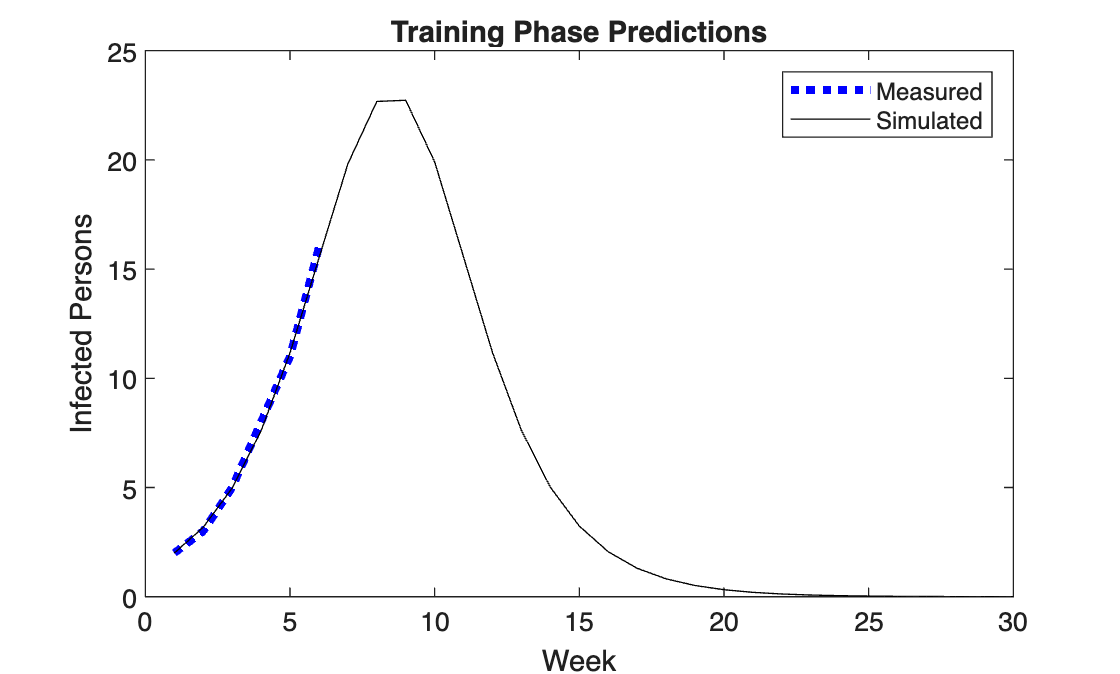

% NOTE: The following is my fitted model
beta = 1 / 90; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / day)
i_1 = 2;       % Initial count of infected persons

% Define initial state
s_1 = 100 - i_1;
r_1 = 0;

% Run simulation
[S_fit, I_fit, R_fit, W_fit] = simulate_sir(s_1, i_1, r_1, beta, gamma, 30);

% Plot the fitted simulation
figure()
plot(W_data, I_data, 'b:', 'LineWidth', 3, 'DisplayName', 'Measured'); hold on
plot(W_fit, I_fit, 'k-', 'DisplayName', 'Simulated')

xlabel("Week")
ylabel("Infected Persons")
legend()
title("Training Phase Predictions")

While the overlap of Measured and Simulated data is *encouraging*, we should maintain a healthy dose of skepticism towards these model results until we *verify* and *validate* the model.

Remember that:

- **Verification** is checking that we *implemented the model correctly*; it's an exercise in coding / math.

- **Validation** is checking that *the model represents reality*; it's an exercise in physics.

ModSim students in 2020 came up with some good mnemonics:

- Verifi**c**ation concerns **c**ode

- Vali**d**ation concerns physical **d**ata

Let's look at some examples of verification and validation!

**Verification Steps:** To build and verify a physical model, we should follow a set of steps:

- *Clearly state* the model in *abstract* terms: the full set of governing equations that define the model.

- *Implement* the model in computer code, for example Matlab

- *Decide* on a set of "facts" about the model results that should be true, based on the *abstract* definition of the model

- *Verify* that the model satisfies those "facts"

Remember that *verification* is an exercise in software development / mathematics: We are *not yet *comparing our model against physical data. Instead, we're just checking to make sure we implemented the model correctly.

For instance, with the two car train example from Worksheet 1, we know that people can only move between the two trains. One "verification fact" we can test is that the sum of people on both train cars remains *constant*. The compartmental SIR model has a similar conservation property.

Writing down a set of "facts" about our model requires that we have some knowledge about our model. For example, when we derived the SIR model equations in `sir_notebook1.mlx`, we took great pains to make sure we didn't lose any individuals. As a reminder, those equations were:


$$S_{t+1} = S_t - \Delta I_t \\
I_{t+1} = I_t + \Delta I_t - \Delta R_t \\
R_{t+1} = R_t + \Delta R_t$$


Since the change terms $\Delta I, \Delta R$ are added and subtracted are carefully balanced across the stocks, the total number of persons *should* be conserved. But we should check that our implementation actually guarantees this!

### **Exercise 1 / 7**

Write down a mathematical expression for the *total number of persons* in the SIR model, based on the stocks $S, I, R$. Compute your expression using `S_fit, I_fit, R_fit` (computed above). Does this model conserve the total number of persons?

*Yes, it does conserve*

*sum = s_fit + i_fit + r_fir*

*(Here's some space for you to write some math using text!)*

% TODO: Compute total persons, plot
% HINT 1: You can copy-paste plotting code from above!
% HINT 2: Your plot might end up looking "boring"....

% NOTE: The following is my fitted model
beta = 1 / 90; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / day)
i_1 = 2;       % Initial count of infected persons

% Define initial state
s_1 = 100 - i_1;
r_1 = 0;

% Run simulation
[S_fit, I_fit, R_fit, W_fit] = simulate_sir(s_1, i_1, r_1, beta, gamma, 30);

% Plot the fitted simulation
figure()
plot(W_data, I_data, 'b:', 'LineWidth', 3, 'DisplayName', 'Measured'); hold on
plot(W_fit, I_fit, 'k-', 'DisplayName', 'Simulated')

xlabel("Week")
ylabel("Infected Persons")
legend()
title("Training Phase Predictions")

However, as some students in 2020's class found, this conservation doesn't hold for **all parameter values:**

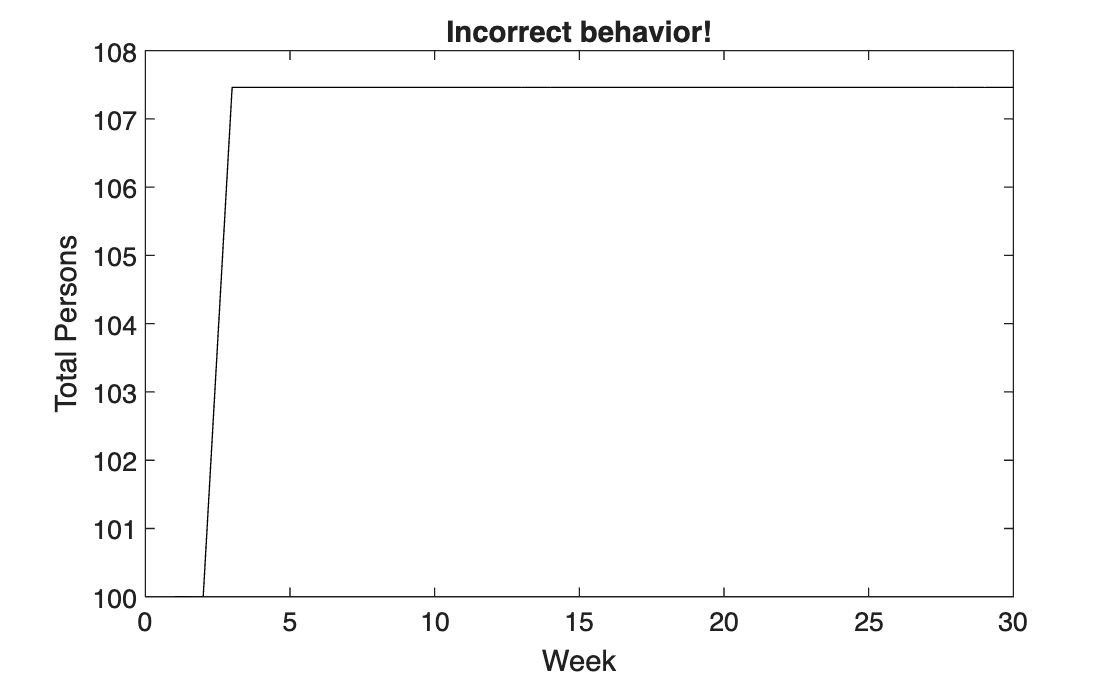

% NOTE: The following is my fitted model
beta = 1 / 10;  % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 16; % Recovery rate (1 / day)
i_1 = 1;        % Initial count of infected persons
n_total = 100;  % Initial population
week_end = 30;  % Simulation period

% Define initial state
s_1 = n_total - i_1;
r_1 = 0;

% Run simulation
[S_iv, I_iv, R_iv, W_iv] = simulate_sir(s_1, i_1, r_1, beta, gamma, week_end);
T_iv = S_iv + I_iv + R_iv;

% Plot the problematic results
figure()
plot(W_iv, T_iv, 'k-')
xlabel("Week")
ylabel("Total Persons")
title("Incorrect behavior!")

This is because the correctness of the $\Delta I, \Delta R$ terms is not enforced well. Let's take a look at the following code from `action_sir.m:`

% This way of enforcing invariants does not actually conserve persons!
%s_n = max(s_n, 0);
%i_n = max(i_n, 0);
%r_n = max(r_n, 0);

These lines prevent the stock values from going below zero. However, they don't prevent stocks from exceeding the total population. Your task in the next couple exercises is to adopt a "verification mindset" by (1) proactively thinking of "verification facts" to check about the model, and (2) updating the model to satisfy those "verification facts."

### "Verification facts"

When doing model verification, you should decide on a large number of "facts" that should follow from your model definition, but which are *not* a direct consequence of something you coded. For instance, if you set the initial number of infected persons to 2, it's not enough to check that `i_1 = 2`. This sort of check is *necessary* *but not sufficient* for model verification. You should instead look for "facts" that are a resulting property of how you developed the model---the conservation of total persons `S + I + R == n_total` is one such example.

*One more tip:* Another great way to verify a model is to give it to someone else and ask if it makes sense. *Peer review* is an excellent way to catch errors (it's what professional scientists do!).

Once we have identified a verification fact, we need to *implement* that fact in code. We can use inequalities to check that various properties hold. MATLAB represents "true" as the value `1`, and "false" as `0:`

1 == 1 % Will return true, which is represented as `1`

ans = logical
   1


1 == 0 % will return false, which is represented as `0`

ans = logical
   0


As you've (hopefully!) noticed, the `assert()` calls in MATLAB help keep you accountable to certain inequalities. I designed these to help you test your code quickly, but you can also use them to help verify a model! An `assert()` statement does nothing if its input is true, but halts execution and shows the message when its input is false:

assert(1 == 1, 'This had better be true!')

We can use (in)equalities to test properties about our stocks:

S_iv + I_iv + R_iv == 100

ans = 1×30 logical array
   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


But MATLAB will make *vector comparisons*; this is too many values to check in an `assert()` statement! We can use the MATLAB function `all()` to check that all of the entries of a vector are true:

all(S_iv + I_iv + R_iv == 100)

ans = logical
   0


However, be careful when checking for exact equality, e.g., `x == 1.0`. The nature of our models is such that conserved quantities will be close to a target value, but not exactly equal. Try using things like `abs(x - 1.0) < 1e-3` instead.

all(abs(S_iv + I_iv + R_iv - 100) < 1e-3)

ans = logical
   0


*Aside:* In computational science, we could call the `1e-3` above a *tolerance.*

Let's practice thinking of verification facts!

### **Exercise 2 / 7**

What other "facts" about the SIR model could you check? Write down at least three verification facts. Describe how you would carry out these checks as `assert()` statements in MATLAB.

*Hint:* There are many other facts we could write down about the stocks. What do you know about the count of people? Think about the stocks individually, and the stocks together as the total.

*(Write your response here)*

the slope of the function, the second derivation, whether Si, Ii, Ri > Total

Coming up with good verification facts is difficult. To help with this, we'll do a round of *peer review *to help improve your list of facts.

### Exercise 3 / 7

### 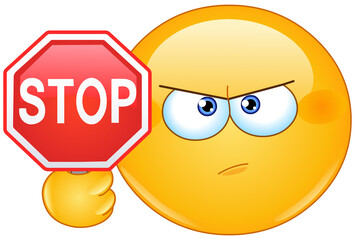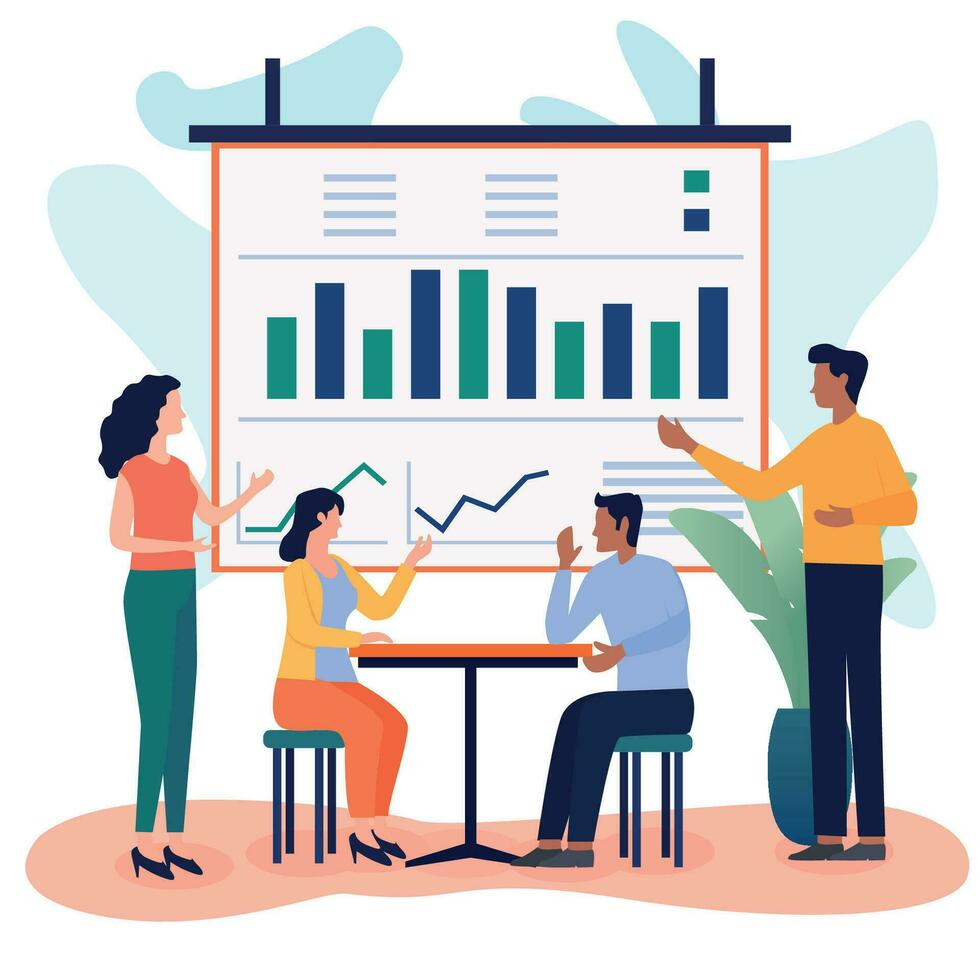

**STOP & DISCUSS:** Talk with one other person at your table and share your verification facts. First, write down their list of facts below:

(*Who did you work with?) Zach*

*(Write your partner's list of verification facts here.) Whether the infected is increasing or decreaseing is a issue or whether recovery is increaseing or decreasing, and whether the three counts exceed the totoal number. *

Next, you will analyze their list of verification facts. Use the following questions to help structure this.

- Do any of your partner's verification facts involve checking something that you **directly set** when running the model? 

Maybe the last one, whether the sum of each one exceeds the total sum

-     For instance, checking that `s_1 >= 0` or `r_1 >= 0` would fall under this category, as we **directly set** `s_1, r_1` when setting up our simulation.

- *    (Identify facts from your partner that fall under this category.)*

-  **Verification facts that check directly set quantities ****are not**** effective verification facts.**

- Do any of your partner's verification facts involve checking something that is **not directly set** when running the model?

-     For instance, the state variables `S(i)` at times greater than the initial time `i > 1` are not directly set. So checking the total number of persons `S(i) + I(i) + R(i)` at all simulation times would fall under this category.

- *    (Identify facts from your partner that fall under this category.)*

*The trend of the numbers of infected and susceptible are indirect set as running the model *

-  **Verification facts that check these "indirect" properties ****are**** effective verification facts.**

**Once you've analyzed your partner's list of verification facts, share your results with them. Use your partner's results to identify the ****effective**** verification facts that you wrote down.**

Now let's put these ideas to use to fix and verify your model!

### Exercise 4 / 7

**Fix the**

** model implementation.** Ensure that it satisfies the conservation property noted above, and all the **effective** verification facts you identified (in Exercise 2). Follow these steps to fix the model:

- Implement your verification facts as `assert()` statements in the space provided below. Target the stock values `S_fix, I_fix, R_fix.`

- Create a new function file called `action_sir_v2.m`. *Hint:* Start by copying `action_sir.m`!

- Create a new function file called `simulate_si`This can be largely the same as `simulate_sir.m`, but should call your new `action_sir_v2()` instead. *Hint:* Start by copying `simulate_sir.m`!`r_v2.m`. 

- Get `simulation_sir_v2()` running successfully (but not necessarily correctly!) before you try making too many changes to your action. Being able to run the code and inspect the diagnostic plots below will help with debugging your model.

**Important note:** Fixing this bug is really important, because your project will start with the code you develop here. **You will have to fix this bug in order to successfully complete the project, so please seek help from the teaching team if you're having trouble with this exercise.**

*Hint 1:* Start by copying old code! You should not write this code from scratch!

*Hint 2:* The "big thing" you need to fix is in the computation of the `infected` and `recovered` values.

*Hint 3: *You don't have access to the total population as an input, but can you *compute* it based on the inputs?



% NOTE: Do not edit this; use this to run your simulation
[S_fix, I_fix, R_fix, W_fix] = simulate_sir_v2(s_1, i_1, r_1, beta, gamma, week_end);

infected = 9.9000

recovered = 0.0625

infected = 89.1000

recovered = 0.6773

infected = 0

recovered = 6.2038

infected = 0

recovered = 5.8160

infected = 0

recovered = 5.4525

infected = 0

recovered = 5.1117

infected = 0

recovered = 4.7923

infected = 0

recovered = 4.4927

infected = 0

recovered = 4.2119

infected = 0

recovered = 3.9487

infected = 0

recovered = 3.7019

infected = 0

recovered = 3.4705

infected = 0

recovered = 3.2536

infected = 0

recovered = 3.0503

infected = 0

recovered = 2.8596

infected = 0

recovered = 2.6809

infected = 0

recovered = 2.5133

infected = 0

recovered = 2.3563

infected = 0

recovered = 2.2090

infected = 0

recovered = 2.0709

infected = 0

recovered = 1.9415

infected = 0

recovered = 1.8202

infected = 0

recovered = 1.7064

infected = 0

recovered = 1.5997

infected = 0

recovered = 1.4998

infected = 0

recovered = 1.4060

infected = 0

recovered = 1.3182

infected = 0

recovered = 1.2358

infected = 0

recovered = 1.1585

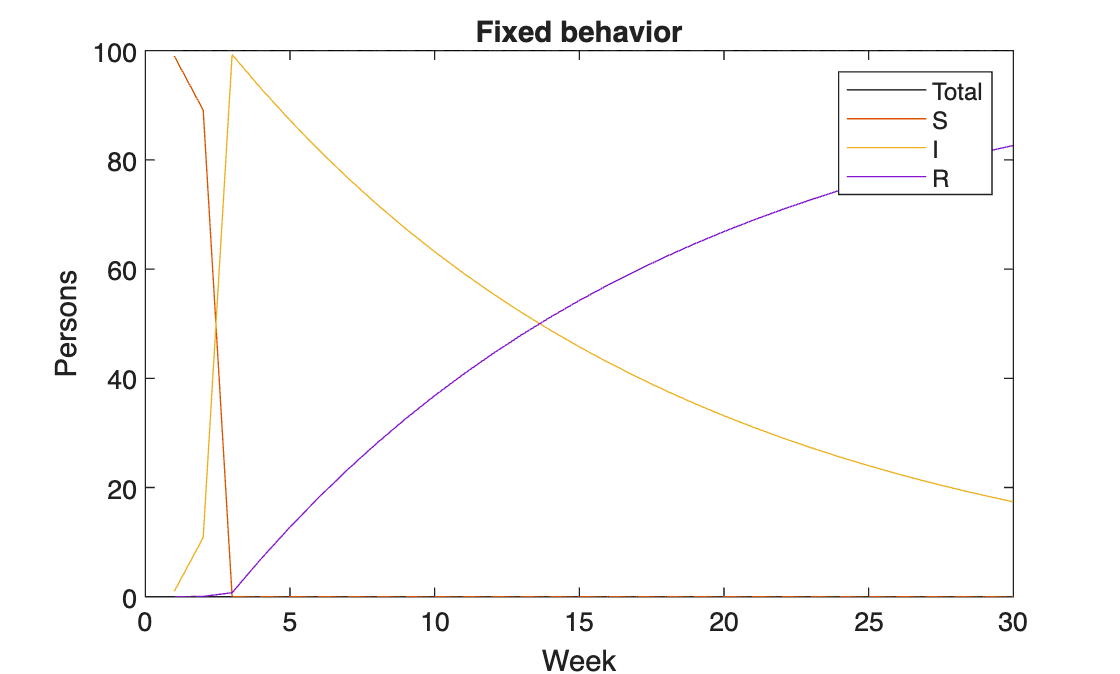

T_fix = S_fix + I_fix + R_fix;

% NOTE: Do not edit this code; Plot multiple diagnostic quantities
figure()
plot(W_fix, T_fix, 'k-', 'DisplayName', 'Total'); hold on
plot(W_fix, S_fix, 'DisplayName', 'S')
plot(W_fix, I_fix, 'DisplayName', 'I')
plot(W_fix, R_fix, 'DisplayName', 'R')
xlabel("Week")
ylabel("Persons")
legend()
title("Fixed behavior")


% TODO: Write your own assertions here; use them to verify your model is correct!

tol = 1e-10;   % deviation
assert(all(S_fix >= -tol), 'Error: S went negative');
assert(all(I_fix >= -tol), 'Error: I went negative');
assert(all(R_fix >= -tol), 'Error: R went negative');

% total conservation
N_fix = S_fix + I_fix + R_fix;
N0 = N_fix(1);   % intial total population
tolN = 1e-1 * N0; % deviation 
assert(max(abs(N_fix - N0)) <= tolN,'Error: Total population not conserved');

%each not exceed total population
assert(all(S_fix <= N0 + tolN), 'Error: S exceeded total N');
assert(all(I_fix <= N0 + tolN), 'Error: I exceeded total N');
assert(all(R_fix <= N0 + tolN), 'Error: R exceeded total N');

**Compare with someone else at your table: Did they manage to fix the model? If yes, how did they do it? If no, what else can you try?**

## Model Validation

Also remember that *verification* is only half of the model evaluation story; verification just checks that we *implemented* the model correctly. We should also check whether the model is a good representation of reality! To do that, we need to *validate* our model.

**Validation Steps:** To build and validate a physical model, we should follow a set of steps:

- *Clearly state* the purpose for which we want to use our model. This should include the scenario we are studying and the questions we want to answer.

- Construct our model based on understanding of the physical phenomena at play.

- Use *training data* to fit the parameters in the model and determine if the model is *flexible* enough to represent the data.

- Use *validation data* to assess whether the model is *trustworthy* enough to support answering our questions.

The *validation data* should lie "outside" our training data, in order to test whether our model is *trustworthy *enough to extrapolate outside what we've seen before. This is important for answering the questions we have about the flu: Remember we were interested in answering:

**Questions**

- When will this flu season be over?

- How many of the 100 total persons will fall ill with the flu?

The training phase results are encouraging, in that they indicate the model can fit behaviors we've seen before. But what about something we haven't seen before? To test if the model is valid for predicting results in the future, we need to check it against data not used in fitting to see if the model as-fit can predict future results. To that end, let's load some additional data to serve validation purposes.

% Load the validation data
tab_data_validate = readtable("wave1.csv", "Delimiter", ",")

tab_data_validate = 18×2 table
    Week    InfectedCount
    ____    _____________

      1           2      
      2           3      
      3           5      
      4           8      
      5          11      
      6          16      
      7          20      
      8          23      
      9          23      
     10          20      
     11          16      
     12          12      
     13           8      
     14           6      
     15           4      
     16           3      


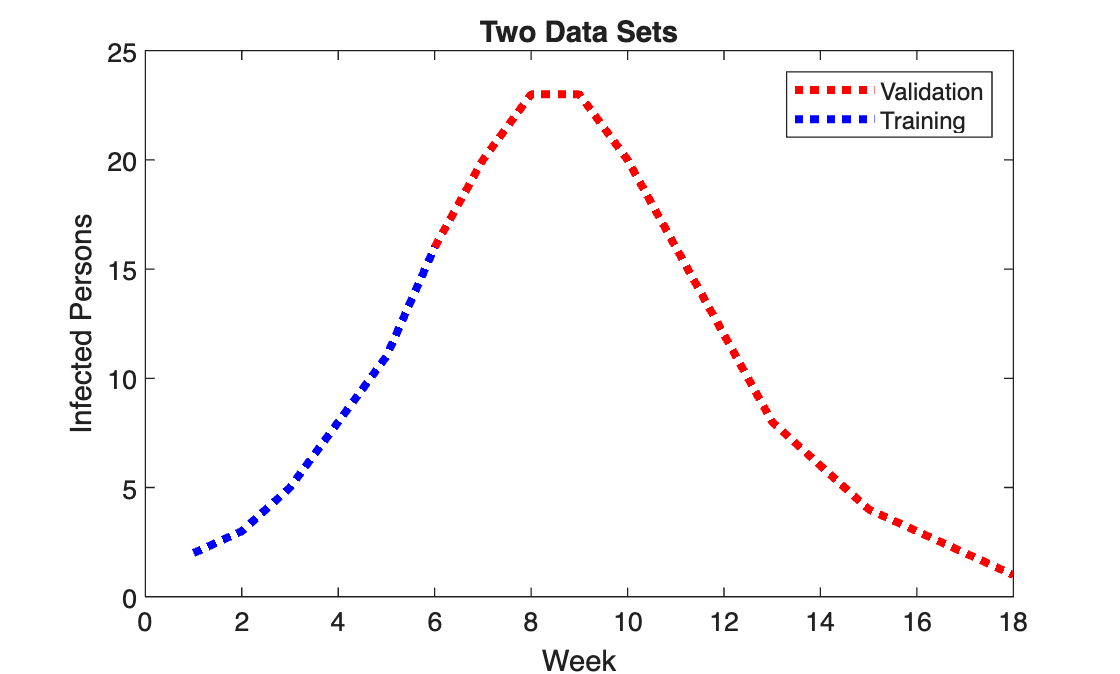


% Plot the training and validation data
figure()
plot(tab_data_validate.Week, tab_data_validate.InfectedCount, 'r:', 'LineWidth', 3, 'DisplayName', 'Validation'); hold on
plot(W_data, I_data, 'b:', 'LineWidth', 3, 'DisplayName', 'Training')
xlabel("Week")
ylabel("Infected Persons")
legend()
title("Two Data Sets")

Notice that the validation data extends beyond the training data. It's important that we do not touch the validation data at all when fitting the model.

Now let's complete the validation exercise by comparing the model against the validation data.

### **Exercise 5 / 7**

Create a plot of `tab_data_validate` against the simulation results `W_fit, I_fit`. Is the model sufficiently accurate for predicting a few weeks into the future?

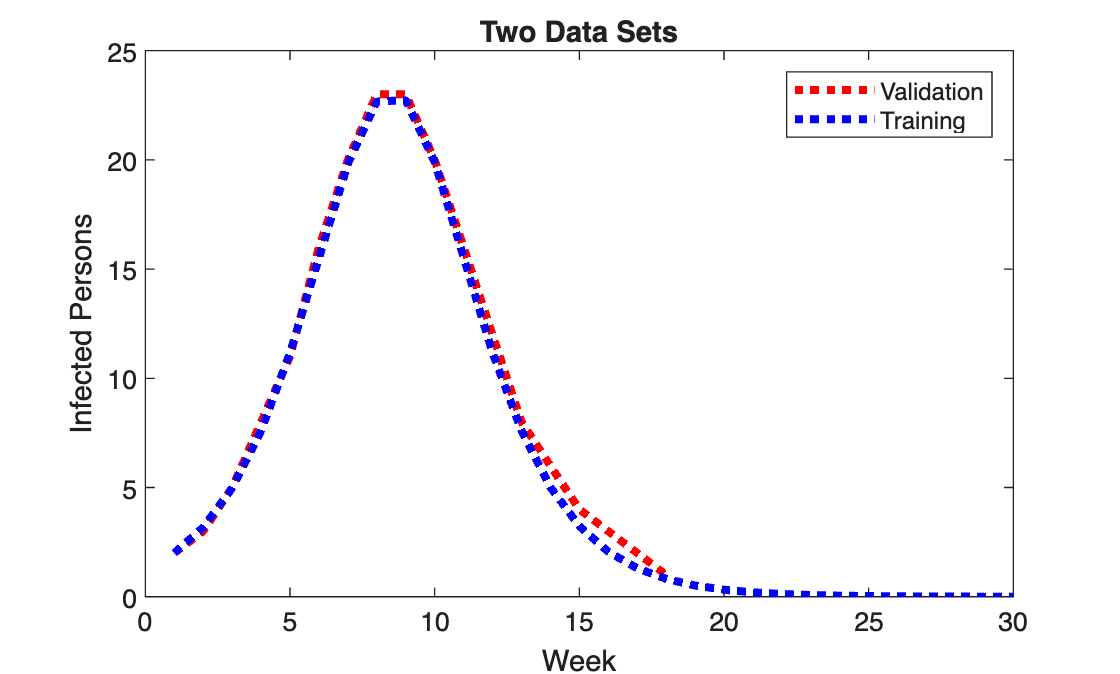

% Plot the training and validation data
figure()
plot(tab_data_validate.Week, tab_data_validate.InfectedCount,'r:', 'LineWidth', 3, 'DisplayName', 'Validation'); hold on
plot(W_fit, I_fit, 'b:', 'LineWidth', 3, 'DisplayName', 'Training')
xlabel("Week")
ylabel("Infected Persons")
legend()
title("Two Data Sets")

*Hint:* See the code above for a hint on how to plot data using a MATLAB table.

Is the model sufficiently accurate for predicting a few weeks into the future?

*It is sufficiently accurate. *

**Important Note: **It may seem circular that we're using data from "the future" (beyond Week 6) to validate the model. In real cases of model validation we will take *historical* data, split it into training and validation sets, and perform the same exercise. In that case, it's important to split the data in a way that matches the way you intend to use the model; for instance, if making predictions in the future, make sure your validation data contains information further forward in time than what's contained in your training data.

**A Productive Mindset:** When building a model, we should maintain a healthy degree of skepticism towards our model. Remember, "All models are wrong, some are useful." *Verification* and *Validation* are concrete ways to put that skepticism into practice: 

Verification: By writing down and testing "facts" about our model, we are checking to make sure we did not introduce any bugs when implementing our model in code.

Validation: By "stress testing" our model with data it hasn't seen before, we can get a sense of how well our model will perform when we use it to predict on scenarios we've not yet seen. 

Verification and validation help us build confidence—but not certainty—that our model will be useful. Why should we have confidence but not certainty? Let's take a look at one way things can go wrong---when *physical phenomena are missing from our model*.

## Missing Physics

We've shown that the model is valid for the purpose of predicting a few weeks into the future. But what about predicting the next flu season? Let's load a second data set to see how well the model performs in that scenario:

% Load the validation data
tab_data_wave2 = readtable("wave2.csv", "Delimiter", ",");

% Configure the simulation
beta = 1 / 90; % Infection rate (New / Susceptible / Infected / day)
gamma = 1 / 2; % Recovery rate (1 / day)
week_end = 100;
i_1 = 2;       % Initial count of infected persons
s_1 = 100 - i_1;
r_1 = 0;

% Run simulation
[S_long, I_long, R_long, W_long] = simulate_sir_v2(s_1, i_1, r_1, beta, gamma, week_end);

infected = 2.1778

recovered = 1

infected = 3.3834

recovered = 1.5889

infected = 5.1070

recovered = 2.4861

infected = 7.3680

recovered = 3.7966

infected = 9.9196

recovered = 5.5823

infected = 12.0646

recovered = 7.7509

infected = 12.7655

recovered = 9.9078

infected = 11.3906

recovered = 11.3367

infected = 8.5413

recovered = 11.3636

infected = 5.5916

recovered = 9.9525

infected = 3.4008

recovered = 7.7720

infected = 2.0223

recovered = 5.5864

infected = 1.2062

recovered = 3.8043

infected = 0.7272

recovered = 2.5053

infected = 0.4430

recovered = 1.6162

infected = 0.2721

recovered = 1.0296

infected = 0.1680

recovered = 0.6508

infected = 0.1042

recovered = 0.4094

infected = 0.0648

recovered = 0.2568

infected = 0.0403

recovered = 0.1608

infected = 0.0251

recovered = 0.1005

infected = 0.0157

recovered = 0.0628

infected = 0.0098

recovered = 0.0392

infected = 0.0061

recovered = 0.0245

infected = 0.0038

recovered = 0.0153

infected = 0.0024

recovered = 0.0096

infected = 0.0015

recovered = 0.0060

infected = 9.2458e-04

recovered = 0.0037

infected = 5.7707e-04

recovered = 0.0023

infected = 3.6018e-04

recovered = 0.0015

infected = 2.2481e-04

recovered = 9.0522e-04

infected = 1.4032e-04

recovered = 5.6502e-04

infected = 8.7582e-05

recovered = 3.5267e-04

infected = 5.4665e-05

recovered = 2.2012e-04

infected = 3.4120e-05

recovered = 1.3739e-04

infected = 2.1297e-05

recovered = 8.5758e-05

infected = 1.3293e-05

recovered = 5.3527e-05

infected = 8.2969e-06

recovered = 3.3410e-05

infected = 5.1787e-06

recovered = 2.0853e-05

infected = 3.2323e-06

recovered = 1.3016e-05

infected = 2.0175e-06

recovered = 8.1242e-06

infected = 1.2593e-06

recovered = 5.0709e-06

infected = 7.8600e-07

recovered = 3.1651e-06

infected = 4.9060e-07

recovered = 1.9755e-06

infected = 3.0621e-07

recovered = 1.2331e-06

infected = 1.9113e-07

recovered = 7.6964e-07

infected = 1.1930e-07

recovered = 4.8038e-07

infected = 7.4461e-08

recovered = 2.9984e-07

infected = 4.6476e-08

recovered = 1.8715e-07

infected = 2.9009e-08

recovered = 1.1681e-07

infected = 1.8106e-08

recovered = 7.2911e-08

infected = 1.1301e-08

recovered = 4.5509e-08

infected = 7.0540e-09

recovered = 2.8405e-08

infected = 4.4029e-09

recovered = 1.7730e-08

infected = 2.7481e-09

recovered = 1.1066e-08

infected = 1.7153e-09

recovered = 6.9072e-09

infected = 1.0706e-09

recovered = 4.3112e-09

infected = 6.6826e-10

recovered = 2.6909e-09

infected = 4.1710e-10

recovered = 1.6796e-09

infected = 2.6034e-10

recovered = 1.0483e-09

infected = 1.6250e-10

recovered = 6.5435e-10

infected = 1.0143e-10

recovered = 4.0842e-10

infected = 6.3307e-11

recovered = 2.5492e-10

infected = 3.9514e-11

recovered = 1.5912e-10

infected = 2.4663e-11

recovered = 9.9315e-11

infected = 1.5394e-11

recovered = 6.1989e-11

infected = 9.6085e-12

recovered = 3.8692e-11

infected = 5.9973e-12

recovered = 2.4150e-11

infected = 3.7433e-12

recovered = 1.5074e-11

infected = 2.3365e-12

recovered = 9.4085e-12

infected = 1.4583e-12

recovered = 5.8725e-12

infected = 9.1025e-13

recovered = 3.6654e-12

infected = 5.6815e-13

recovered = 2.2878e-12

infected = 3.5462e-13

recovered = 1.4280e-12

infected = 2.2134e-13

recovered = 8.9131e-13

infected = 1.3816e-13

recovered = 5.5632e-13

infected = 8.6232e-14

recovered = 3.4724e-13

infected = 5.3823e-14

recovered = 2.1674e-13

infected = 3.3595e-14

recovered = 1.3528e-13

infected = 2.0969e-14

recovered = 8.4437e-14

infected = 1.3088e-14

recovered = 5.2703e-14

infected = 8.1691e-15

recovered = 3.2895e-14

infected = 5.0989e-15

recovered = 2.0532e-14

infected = 3.1826e-15

recovered = 1.2816e-14

infected = 1.9865e-15

recovered = 7.9991e-15

infected = 1.2399e-15

recovered = 4.9928e-15

infected = 7.7390e-16

recovered = 3.1163e-15

infected = 4.8304e-16

recovered = 1.9451e-15

infected = 3.0150e-16

recovered = 1.2141e-15

infected = 1.8819e-16

recovered = 7.5779e-16

infected = 1.1746e-16

recovered = 4.7299e-16

infected = 7.3314e-17

recovered = 2.9522e-16

infected = 4.5760e-17

recovered = 1.8427e-16

infected = 2.8562e-17

recovered = 1.1501e-16

infected = 1.7828e-17

recovered = 7.1788e-17

infected = 1.1127e-17

recovered = 4.4808e-17

infected = 6.9454e-18

recovered = 2.7968e-17

infected = 4.3351e-18

recovered = 1.7457e-17

infected = 2.7058e-18

recovered = 1.0896e-17

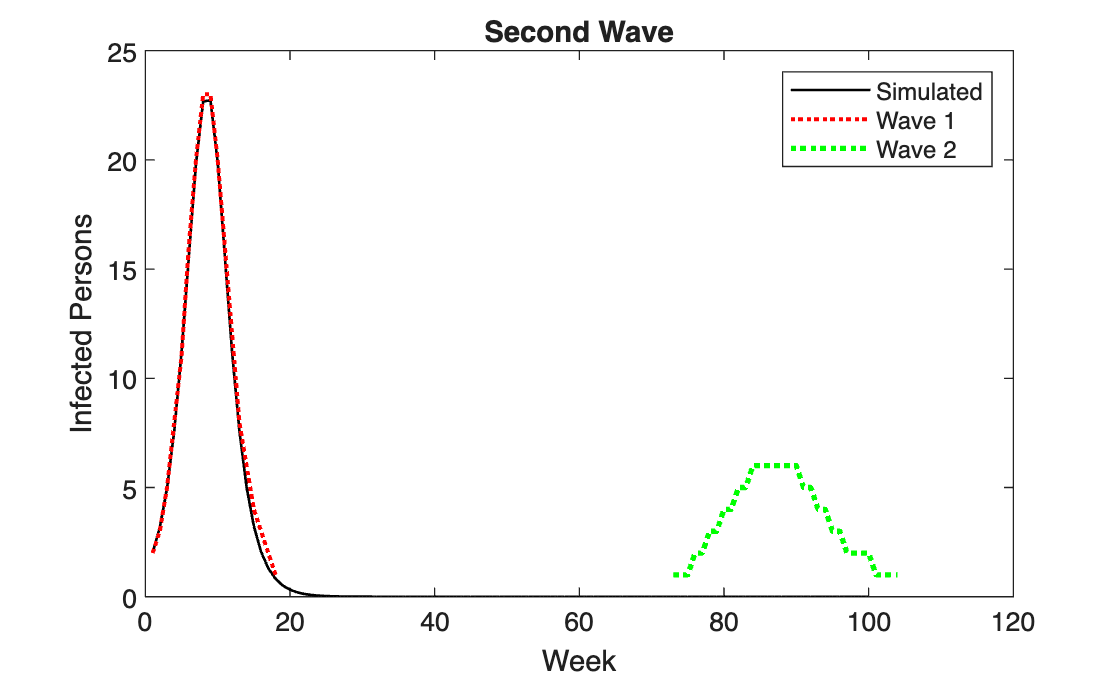


% Plot the fitted simulation
figure()
plot(W_long, I_long, 'k-', 'LineWidth', 1, 'DisplayName', 'Simulated'); hold on
plot(tab_data_validate.Week, tab_data_validate.InfectedCount, 'r:', 'LineWidth', 1.5, 'DisplayName', 'Wave 1')
plot(tab_data_wave2.Week, tab_data_wave2.InfectedCount, 'g:', 'LineWidth', 2.0, 'DisplayName', 'Wave 2')
xlabel("Week")
ylabel("Infected Persons")
legend()
title("Second Wave")

The model is totally invalid for predicting the next flu season! It does not exhibit a second wave at all.

### **Exercise 6 / 7**

Try tweaking the parameters `beta, gamma, i_1` to match this second wave phenomena. Convince yourself that it is not possible to represent both the first and second wave with the present model.

*(You can tweak the parameters in the code chunk above; document your findings in this section.)*

**increase b, the peak is early, but no second waves. decrease b, the peak is late, but no second waves. decrease gamma, the peak is long, increase gamma was the opposite. But all of them have a second wave**

Let's think about why our present model can't represent this second wave. Remember the stock and flow diagram for this model:

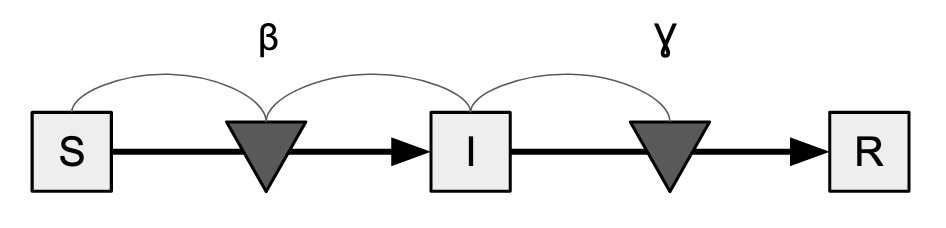

This stock and flow diagram has just two flows, Infections carry individuals from S to I, and Recoveries carry individuals from I to R. In this model *only Susceptible* *persons can become Infected*. 

### **Exercise 7 / 7**

Answer the following questions:

- What *physical causes* could lead to a person getting re-infected with the flu? Name at least two possible causes. *Hint:* The US Centers for Disease for Disease Control and Prevention (CDC) publishes articles on [this topic](https://www.cdc.gov/flu/about/viruses/change.htm).

*the virus will evolve, and the people's imuuse system sometimts degrade*

- How could we *represent* these physical causes in our model? What *additional flow* would you add to the model, what information links would this new flow have, and what physical mechanism(s) would this represent?

the seaonal flu will influenced by seaons. We can simulate it by types of period function

- *    Hint: While the CDC talks about genetic changes, we **cannot** use randomness to represent these changes in a stock-and-flow model. Remember that a strock-and-flow model *uniquely* defines a set of action update equations. In Module 3 / Worksheet 5, we'll talk more about randomness, and how we can use it in a principled way to represent uncertainty.*

*Nerdy aside:* The evolution of species is theorized to involve a peculiar process called [punctuated equilibrium](https://en.wikipedia.org/wiki/Punctuated_equilibrium): a usual state of affairs with slow change interrupted by occasional rapid change. Influenza is thought to undergo a [similar evolutionary trajectory](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC4124202/).

**Talk with someone at your table and compare your responses. What approach would they take to change the stock-and-flow model to exhibit the re-infection phenomenon?**

### Bonus Exercise

In the project, you will need to edit the compartmental SIR model in such a way that it can represent the second wave shown above. If you make it to this point, try following these steps:

- Update the stock and flow diagram to account for re-infectivitiy

- Update the model action to match your new diagram

- Attempt to fit your model to the Wave 1 and Wave 2 data simultaneously